# Replicating EMG Fatigue Results

## Clear Workspace

Optional step. We don't want variables from other scripts to interfere.

clear variables
clear offline_data_analysis_ripple
clc

## Load Data

Data was recorded using the Ripple system, and it was saved as a `.ns2` file. I am using a script written by Tyler to import the image into a MATLAB-readable format.

[head, data] = read_nsx_file('File', '..\..\..\data\01_iso-single_chan-biceps\biceps-2-5-min.ns2');

Loading 0.0 GB of data


## Validate Raw Data

Look at the Power Spectral Density and the Spectrogram using the Signal Analyzer app. Make sure there aren't any artifacts before proceeding.

Keep in mind that you will ususally have applied filters during the recording.

fs = head.Fs;
ch_idx = 1;
ch_signal = data(ch_idx, :);
fprintf("Data from channel %02d sampled at %d kHz", ch_idx, fs);

Data from channel 01 sampled at 1000 kHz

signalAnalyzer(ch_signal, 'SampleRate', fs);

## Extract Power Spectrum Information

% Parameters
timeLimits = [0 (length(ch_signal)-1)/fs]; % seconds
frequencyLimits = [0 fs/2]; % Hz

% Index into signal time region of interest
ch_signal_ROI = ch_signal(:);
startTime = 0; % seconds
minIdx = ceil( max((timeLimits(1) - startTime) * fs, 0)) + 1;
maxIdx = floor( min((timeLimits(2) - startTime) * fs, length(ch_signal_ROI) -1)) + 1;
ch_signal_ROI = ch_signal_ROI(minIdx:maxIdx);

% Compute spectral estimate
% Run the function call below without output arguments to plot the results
[Pch_signal_ROI, Fch_signal_ROI] = pspectrum(double(ch_signal_ROI),fs, ...
    'FrequencyLimits',frequencyLimits);

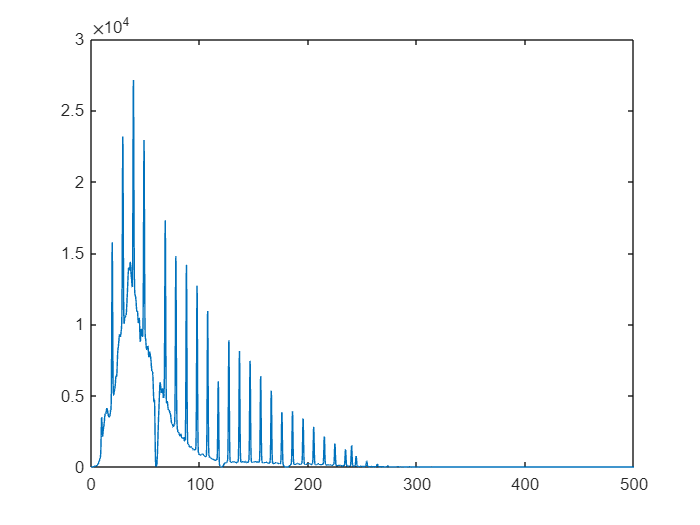

plot(Fch_signal_ROI, Pch_signal_ROI)

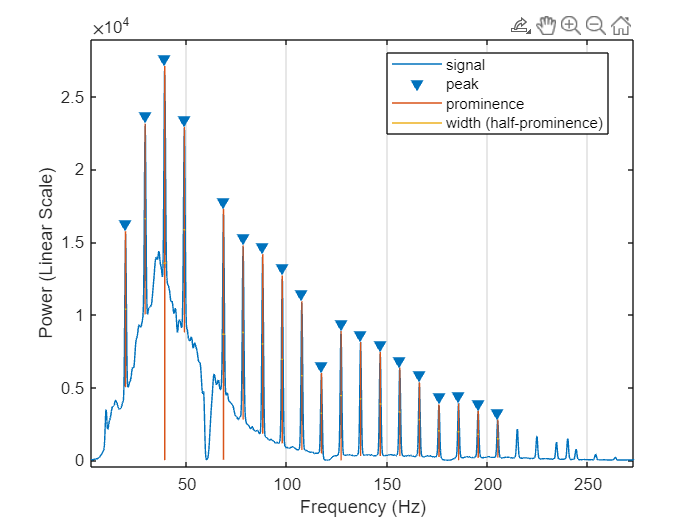

findpeaks(Pch_signal_ROI, Fch_signal_ROI, 'MinPeakProminence', 2000, 'Annotate', 'extents')

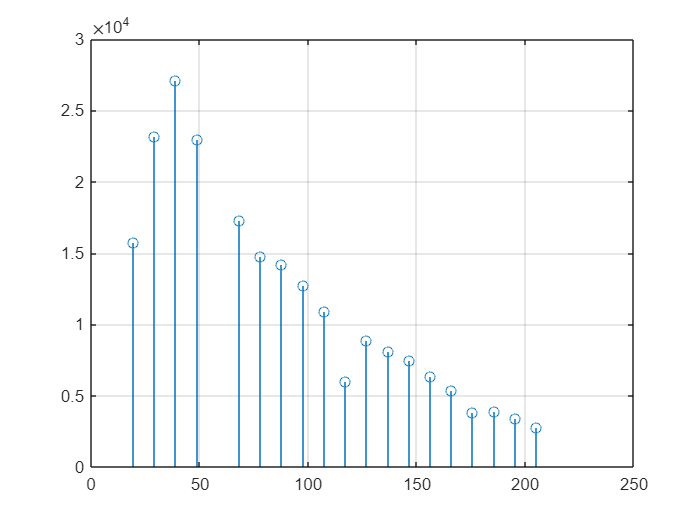

[pks,locs] = findpeaks(Pch_signal_ROI, Fch_signal_ROI, 'MinPeakProminence', 2000, 'Annotate', 'extents');
stem(locs, pks)

locs_mods = mod(locs,  locs(1))

locs_mods =          0
    9.7680
         0
    9.7680
    9.7680
         0
    9.7680
         0
    9.7680
         0


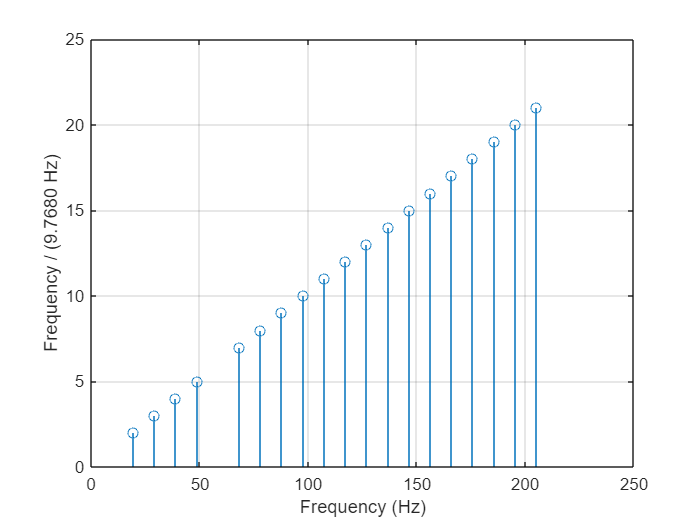

stem(locs, locs/9.7680)

## Apply bandpass filter to signal

This should not change anything since the Ripple device already filters the data between 15 Hz and 375 Hz (**Check your settings**).

If you decide to apply a filter anyway, use `filtfilt()` to avoid introducing phase shifting.

filt_order = 5;
f_nyq = fs /2;
fc_1 = 5;
fc_2 = 499;
[b, a] = butter(filt_order, [fc_1, fc_2]/f_nyq, 'bandpass');
ch_signal_filt = filtfilt(b, a, double(ch_signal));

## Plot the filtered signal

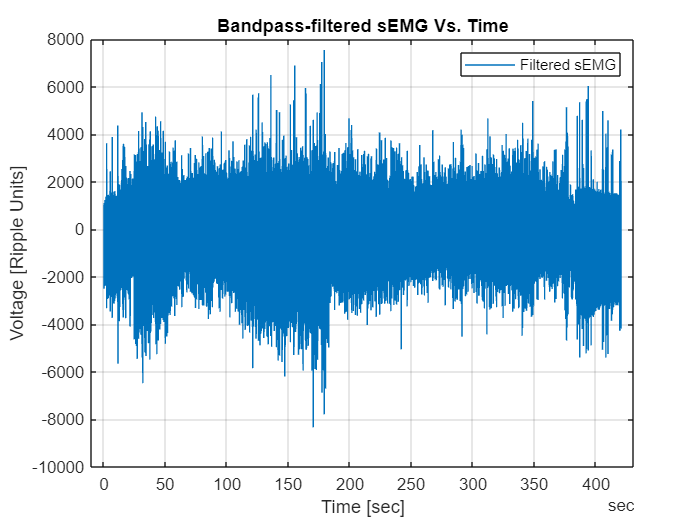

figure()
ch_signal_filt_tb = timetable(ch_signal_filt', 'SampleRate', fs);
plot(ch_signal_filt_tb.Time, ch_signal_filt_tb.Var1)
grid on
legend("Filtered sEMG")
title("Bandpass-filtered sEMG Vs. Time")
xlabel("Time [sec]")
ylabel("Voltage [Ripple Units]")

## Validate Filtered Signal

signalAnalyzer(ch_signal_filt, 'SampleRate', fs)

## Compute Median Frequency (MDF)

It's hard to find window sizes in the literature, but in the paper by Sun et al. They use a 0.1 sec window as benchmark for their neuromorpihc fatigue tracker chip.

We also need to find a way to apply sliding window functions more efficiently.

moving_MDF = @(x)medfreq(x, fs);

window_length = 0.25*fs;

output = zeros(length(ch_signal_filt), 1);

parfor i = 1:length(ch_signal_filt) - window_length
    window_signal = ch_signal_filt(1, i:i+window_length);
    output(i) = moving_MDF(window_signal);
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 12).


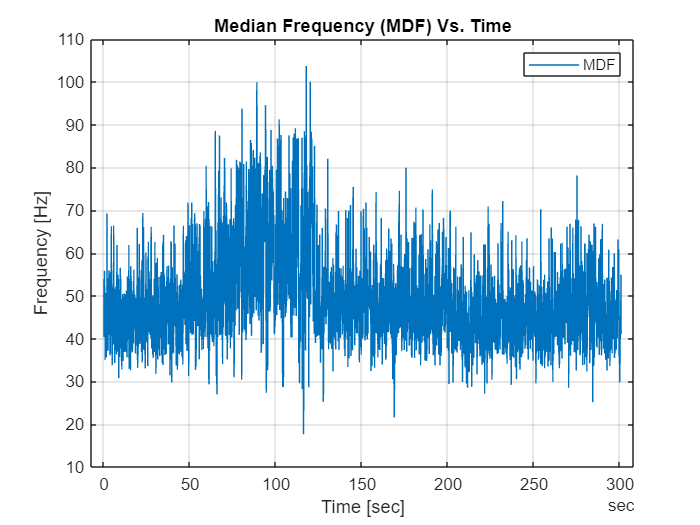

ch_mdf = output(60*fs:end-60*fs,:);
ch_signal_mdf_tb = timetable(ch_mdf, 'SampleRate', fs);
figure()
plot(ch_signal_mdf_tb.Time, ch_signal_mdf_tb.ch_mdf)
grid on
legend("MDF")
title("Median Frequency (MDF) Vs. Time")
xlabel("Time [sec]")
ylabel("Frequency [Hz]")

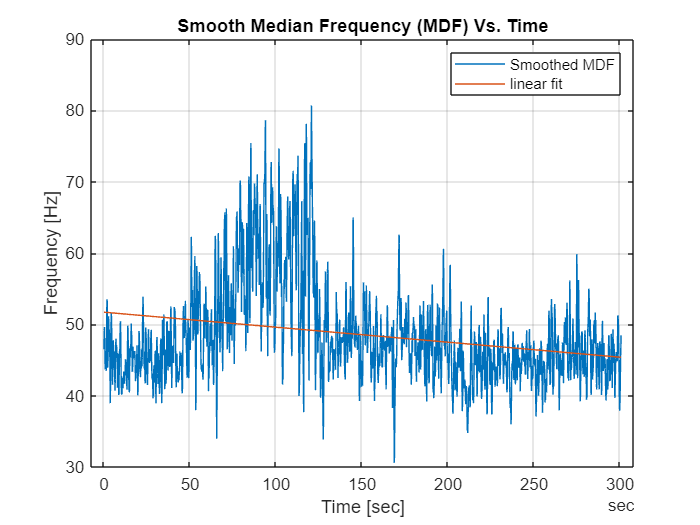

ch_signal_smooth_mdf_tb = timetable(movmean(ch_mdf, 0.5*fs), 'SampleRate', fs);


figure()
plot(ch_signal_smooth_mdf_tb.Time, ch_signal_smooth_mdf_tb.Var1)
grid on
title("Smooth Median Frequency (MDF) Vs. Time")
xlabel("Time [sec]")
ylabel("Frequency [Hz]")
hold on
p = polyfit(time2num(ch_signal_smooth_mdf_tb.Time, 'seconds'), double(ch_signal_smooth_mdf_tb.Var1),1);
f = polyval(p,time2num(ch_signal_smooth_mdf_tb.Time, 'seconds')); 
plot(ch_signal_smooth_mdf_tb.Time,f,'-') 
legend('Smoothed MDF','linear fit')

data_init = ch_mdf(1:60*fs);
data_fin = ch_mdf(end-60*fs:end-1);

adtest(data_init)

ans = logical
   1


adtest(data_fin)

ans = logical
   1


[p,h] = signrank(data_init, data_fin, 'alpha', 0.01)

p = 6.2514e-139

h = logical
   1


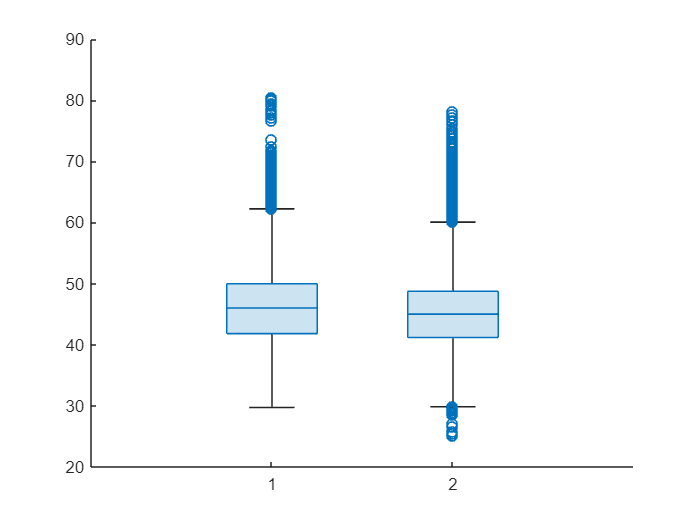

box_data = [data_init data_fin];
figure()
boxchart(box_data)